# Introduction to Constrained Nonlinear Minimization

Minimize the function 


$$\ln (1 + 3(y - (x^3 - x))^2 + (x - 4/3)^2)

$$


subject to upper and lower bounds.

clc; close all; clear all;

## Objective function

Create an anonymous function that returns the value of our expression. 

objfcn = @(x,y) log( 1 + 3*(y - (x.^3 - x)).^2 + (x - 4/3).^2 );

## Plot the objective

Plot it, changing the viewing angle.

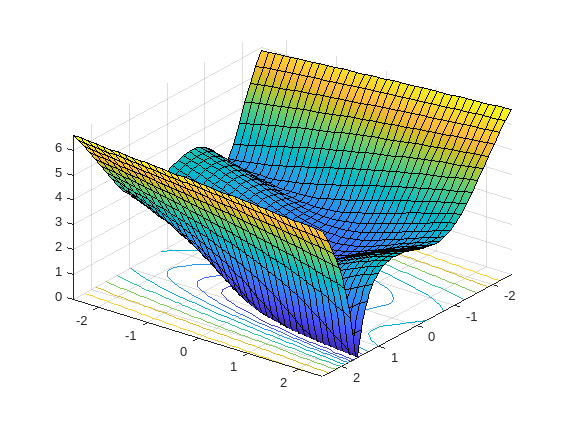

fsurf(objfcn,[-2.5 2.5],'ShowContours','on')
view(127,38)

## Problem

Create an optimization problem to hold the objective, constraints, and variables.

prob = optimproblem

prob =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [0×0 struct] containing 0 OptimizationVariables
         Objective: [0×0 OptimizationExpression]
       Constraints: [0×0 struct] containing 0 OptimizationConstraints

  No problem defined.


## Variables

Create optimization variables, giving each a display name to match their workspace names. Include the upper and lower bound constraints. They can also be specified with dot notation.

x = optimvar('x','LowerBound',-2.5,'UpperBound',2.5);
y = optimvar('y','LowerBound',-2.5,'UpperBound',2.5);

## Set optimization options, and optimize

Convert the objective function to an optimization expression. Variables that are in an expression of a problem are automatically added to the problem. 

prob.Objective = fcn2optimexpr(objfcn,x,y);

In this example, the function to use as the objective function was previously defined as a MATLAB function so it could be plotted. If the function were not already defined, we could specify it using an optimization expression as follows:

Define an initial point.

initialpt.x = -1;
initialpt.y = 2;

Create an options object suited to the type of objective and constraints by passing the problem to optimoptions. 

options = optimoptions(prob,'Display','iter','OutputFcn',@plotUpdate);

Solve the problem.

[sol,fval,exitflag,output] = solve(prob,initialpt,'Options',options);

Solving problem using fmincon.


'plotUpdate' is not found in the current folder or on the MATLAB path, but exists in:
    /home/paragmraw/Coding/MATLAB-course/Day 5

Change the MATLAB current folder or add its folder to the MATLAB path.

Error in optim.problemdef.OptimizationProblem/solve

disp("# of function evaluations: " + output.funcCount)
fval
sol
exitflag

## Optimizing with User-supplied gradient and Hessian

Many of the function evaluations are from the finite-difference calculation fmincon does in order to approximate the gradient, as seen below.

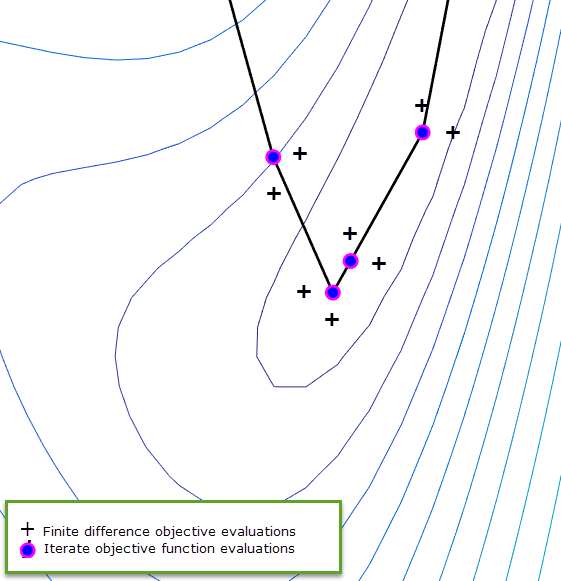

These extra function evaluations can take a considerable amount of time. This example problem only has 2 variables, but if you're solving a problem that has 50 variables, that's 50 extra function evaluations that fmincon has to do at each step. Luckily, there are 2 ways we can speed this up:

- Supply the solver with functions that calculate the gradient and Hessian 

- Use parallel computing (see 'UseParallel' option)

We'll focus on method 1 for now:

To use the gradient and Hessian, first convert the problem to solver-based form with `prob2struct`.

solverprob = prob2struct(prob);

The function returns a structure with problem data and generates a file named "generatedObjective.m" which computes the objective function. Edit this file where indicated to supply the gradient by calling the gradient function `gradfcn` .

edit generatedObjective.m

The file editedObjective.m is a saved copy of the edited file. Replace the `objective` field in the problem structure with the renamed function.

solverprob.objective = @editedObjective;

Set an initial point, options for supplying gradient and Hessian, and provide the Hessian function. 

solverprob.x0 = [-1; 2];

options.SpecifyObjectiveGradient = true;
options.HessianFcn = @hessfcn;
solverprob.options = options;

For this problem, the automatically selected solver is `fmincon`. Verify this by displaying the class of the options object. Solve using `fmincon`.

disp("Options class: " + class(options))
[~,fval,exitflag,output] = fmincon(solverprob);
fval
exitflag
disp("# of function evaluations: " + output.funcCount)

## Using Symbolic Math

Gradient and Hessian expressions can get quite long, even for this example. Alternatively, you can use Symbolic Math Toolbox to automatically calculate the gradient and Hessian functions for you.

Create symbolic variables.

syms xsym ysym

Define objective and use Symbolic Math functions for gradient and Hessian.

f = log( 1 + 3*(ysym - (xsym^3 - xsym))^2 + (xsym - 4/3)^2 );
g = gradient(f);
h = hessian(f);

Convert symbolic expressions into MATLAB functions. The functions group the variables into a single vector which is the format used in the solver-based approach.

obj = matlabFunction(f,'vars',{[xsym;ysym]});
grad = matlabFunction(g,'vars',{[xsym;ysym]});
hess = matlabFunction(h,'vars',{[xsym;ysym]});

Setup and run the optimization with the solver-based approach.The `deal` function returns the values from `obj` and `grad` in the form that `fmincon` requires. Pass the arguments to `fmincon` instead of using the problem structure.

options = optimoptions('fmincon',...
    'SpecifyObjectiveGradient',true,...
    'HessianFcn',@(x,~)hess(x),...
    'Display','iter',...
    'outputfcn',@plotUpdate);

objAndGrad = @(x) deal(obj(x),grad(x));

[~,fval,exitflag,output] = fmincon(objAndGrad,[-1;2],[],[],[],[],...
    solverprob.lb,solverprob.ub,[],options);  
fval
exitflag
disp("# of function evaluations: " + output.funcCount)

Copyright 2010-2019, The MathWorks, Inc.